# Plot figure 3

## Load data

addpath(genpath('../public_code'))

## Make some code that plot the same thing for each set of before / after drug

nstrain_s2_set = {'male_before_timp_180511', ...
               'male_after_timp_180526', ...
               'female_before_timp_180413', ...
               'female_after_timp_180430', ...
               'male_before_bsa_200713' , ...
               'male_after_bsa_200727' };

nstrain_subn_set = {'male_before_timp_180511', ...
               'male_after_timp_180526', ...
               'female_before_timp_180413_sub13mice', ...
               'female_after_timp_180430_sub13mice', ...
               'male_before_bsa_200713_sub9mice' , ...
               'male_after_bsa_200727_sub9mice' };

ttscheme = '1h'; ntest = 6; 
llh2_ntest = {};
llh2_alldata = {};
mi2 = {};

s3 = {};
jij2_alldata = {};
hir2_alldata = {};



didf2 = [0, 4; 5, 9];
count = 0;
for i = 1:6 
    nstrain = nstrain_s2_set{i};
    nstrain_subn = nstrain_subn_set{i};
    for j = 1:2

        count = count + 1; 
        di = didf2(j,1);
        df = didf2(j,2);

        sub_flag = 1;

     
        s2 = my_load_data(nstrain, di, df, sub_flag);

        s3{count} = s2;
        %%
        fp = ['sme_pairwise_l2_' nstrain_subn '_di' num2str(di) ...
            '_df' num2str(df) '_' ttscheme '_beta0.mat'];
        load(fp,'jijFinal_alldata','hirFinal_alldata',...
            'jijFinal3','hirFinal3');

        jij2_alldata{count} = jijFinal_alldata;
        hir2_alldata{count} = hirFinal_alldata;

        llh2_alldata{count} = ...
            compute_loglikelihood(jijFinal_alldata, hirFinal_alldata, s2);

        mi2{count} = compute_mi(s2, jijFinal_alldata, hirFinal_alldata);

        llh2_alldata(count, :, :) = ...
            compute_loglikelihood(jijFinal_alldata, hirFinal_alldata, s2);
        for itest = 1:ntest
            llh2_ntest(count, :,:,itest) = ...
                compute_loglikelihood(jijFinal3, hirFinal_alldata, s2);
        end
    end
end


nNodes2 = [15, 13, 9];
nEdges2 = nNodes2.*(nNodes2-1)/2;
nStates = 4;

cohort_name = 'male_timp'; % This gives Figure 3
% cohort_name = 'male_bsa'; % This gives Figure 3 - supplement 1
% cohort_name = 'female_timp'; % This gives Figure 3 - supplement 2

if strcmp(cohort_name, 'male_timp')
    count_start = 0;
    nEdges = nEdges2(1);
    nNodes = nNodes2(1);
    drug_name = 'TIMP';
elseif strcmp(cohort_name, 'female_timp')
    count_start = 4;
    nEdges = nEdges2(2);
    nNodes = nNodes2(2);
    drug_name = 'TIMP';
elseif strcmp(cohort_name, 'male_bsa')
    count_start = 8;
    nEdges = nEdges2(3);
    nNodes = nNodes2(3);
    drug_name = 'BSA';
end

jij2_5day4 = [];
jij2_flat = [];
hir2_5day4 = [];
dh_5day4 = [];
mi2_5day4 = [];
llh2_5day4 = zeros(3, nNodes, 4);

for i = 1:4
    jij2_5day4 = [jij2_5day4 jij2_alldata{count_start+i}];
    jij2_flat = [jij2_flat jij2_alldata{count_start+i}'];


    dh_5day4 = [dh_5day4 ...
                hir_to_dh(hir2_alldata{count_start+i}, ...
                          nNodes, nStates)];
    
    hir2_5day4 = [hir2_5day4 hir2_alldata{count_start+i}];
    mi2_5day4 = [mi2_5day4 mi2{count_start+i}];
    llh2_5day4(:,:,i) = llh2_alldata{count_start+i};
end



## Check mean of J same or different: perform t-test on equal mean

%
%% Test between 5 days before and after timp
pt2 = zeros(4);
pf2 = zeros(4);
for icohort = 1:4
    for jcohort = 1:4
        [~,pt] = ttest2(jij2_alldata{icohort+count_start},...
            jij2_alldata{jcohort + count_start});
        [~,pf] = vartest2(jij2_alldata{icohort+count_start},...
            jij2_alldata{jcohort + count_start});

        pt2(icohort, jcohort) = pt;
        pf2(icohort, jcohort) = pf;
    end
end


## Figure 3B, 3-supplement 1B, 3-supplement 2B: Plot J_ij, the pairwise interaction, from the pairwise interaction model learned from 5-day aggregate data before / after drug

pMat_var_jij6hr = zeros(4);

for idata = 1:3
    for jdata = idata+1:4
        [~, p] = vartest2(jij2_5day4(:,idata), jij2_5day4(:,jdata)); 
        pMat_var_jij6hr(idata, jdata) = p;
    end
end


figure()
swarmchart([ones(1,nEdges)*1, ones(1,nEdges)*2, ...
    ones(1,nEdges)*3, ones(1,nEdges)*4], ...
    jij2_flat,36,'k.')
xticks([1,2,3,4])
xticklabels({['day 1~5, before ' drug_name],...
    ['day 6~10, before ' drug_name],...
    ['day 1~5, after ' drug_name],...
    ['day 6~10, after ' drug_name]})
set(gca,'fontsize',12)
ylabel('Interaction, J_{ij}')
box on
xlim([0 5])
ylim([-0.2 1.1])

disp('p-value for F-test for equal variance')
disp('first 5 days before TIMP vs. first 5 days after TIMP :')
disp(num2str(pMat_var_jij6hr(1,3)))
disp('last 5 days before TIMP vs. first 5 days after TIMP :')
disp(num2str(pMat_var_jij6hr(2,3)))
disp('first 5 days after TIMP vs. last 5 days after TIMP :')
disp(num2str(pMat_var_jij6hr(3,4)))

hold on


% Check if we use Bonferroni correction or not
% let's not..

p-value for F-test for equal variance


nsigtest = 1;

first 5 days before TIMP vs. first 5 days after TIMP :


my_pvalue = pMat_var_jij6hr(1,3);

0.67193


txt_star = txt_star_from_pvalue(my_pvalue, nsigtest);

last 5 days before TIMP vs. first 5 days after TIMP :


txt = [ txt_star ', p = ' num2str(my_pvalue,2)];

0.68109


plot([1 3],[1 1]*0.9,'k')

first 5 days after TIMP vs. last 5 days after TIMP :


text(2, 0.9, txt,'FontSize',11, ...

0.31443


    'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

my_pvalue = pMat_var_jij6hr(2,3);
txt_star = txt_star_from_pvalue(my_pvalue, nsigtest);
txt = [ txt_star ', p = ' num2str(my_pvalue,2)];
plot([2 3],[1 1]*0.8,'k')
text(2.5, 0.8, txt,'FontSize',11, ...
    'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

my_pvalue = pMat_var_jij6hr(3,4);
txt_star = txt_star_from_pvalue(my_pvalue, nsigtest);
txt = [ txt_star ', p = ' num2str(my_pvalue,2)];
plot([3 4],[1 1]*0.7,'k')
text(3.5, 0.7, txt,'FontSize',11, ...
    'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

txt = 'F-test on equal \sigma_J';
text(4.9, 1.1, txt,'FontSize',11, ...
    'HorizontalAlignment','right',...
    'VerticalAlignment','top');

hold off
set(gca,'fontsize',12)

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 4, 4]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [4, 4]);  
% % print(gcf, 'cll_5day_m1_v2.pdf', '-dpdf');
% print(gcf, 'jij_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'jij_5day_f1_timp.svg', '-dsvg');
print(gcf, 'jij_5day_m4_bsa.svg', '-dsvg');


## Figure 3C, 3-supplement 1C, 3-supplement 2C: Plot Δh_i, the food preference, from the pairwise interaction model learned from 5-day aggregate data before / after drug

figure()
plot(dh_5day4','-','color',[0 0 0]+0.75)
hold on
plot(dh_5day4','k.','markerSize',10)
hold off
xticks([1,2,3,4])
xticklabels({['day 1~5, before ' drug_name],...
    ['day 6~10, before ' drug_name],...
    ['day 1~5, after ' drug_name],...
    ['day 6~10, after ' drug_name]})
set(gca,'fontsize',12)

ylabel('Food preference, \Deltah_{i}')
xlim([0 5])
ylim([-1 4.8])

pMat_dh = zeros(4);
for idata = 1:3
    for jdata = idata+1:4
        [h,p] = ttest2(dh_5day4(:,idata), ...
            dh_5day4(:,jdata),...
            'Vartype','unequal');
        pMat_dh(idata,jdata) = p;
    end
end

disp('p-value for t-test on equal mean')
disp(pMat_dh)

hold on

% pairs to compare 
pair_data = [1,3;2,3;3,4];
height2 = [4., 3.5, 3.];
for ipair = 1:3
    my_pvalue = pMat_dh(pair_data(ipair,1),...
                        pair_data(ipair,2));
    txt_star = txt_star_from_pvalue(my_pvalue, nsigtest);
    txt = [txt_star ', p = ' num2str(my_pvalue,2)];
    plot([pair_data(ipair,1),...
          pair_data(ipair,2)],[1 1]*height2(ipair),'k')

p-value for t-test on equal mean


    text((pair_data(ipair,1)+pair_data(ipair,2))/2, ...

         0    0.4977    0.0027    0.0079
         0         0    0.0011    0.0030
         0         0         0    0.7599
         0         0         0         0


        height2(ipair), txt,'FontSize',11, ...
        'HorizontalAlignment','center',...
        'VerticalAlignment','bottom');
end

txt = 't-test on equal mean';
text(4.9, 4.8, txt,'FontSize',11, ...
    'HorizontalAlignment','right',...
    'VerticalAlignment','top');

hold off

set(gca,'fontsize',12)
% 
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 4, 4]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [4, 4]);  
% % print(gcf, 'cll_5day_m1_v2.pdf', '-dpdf');
% print(gcf, 'dh_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'dh_5day_f1_timp.svg', '-dsvg');
print(gcf, 'dh_5day_m4_bsa.svg', '-dsvg');


## Figure 3D, 3-supplement 1D, 3-supplement 2D: Plot mutual information Plot conditional log-likelihood

% try plotting both l(1,2) and l(1) at the same plot

figure()
plot((1:4)-0.1, squeeze(llh2_5day4(3,:,:))','color',[0 0 0]+0.9)
hold on
plot((1:4)-0.1, squeeze(llh2_5day4(3,:,:))','r.','MarkerSize',10)
plot((1:4)+0.1, squeeze(llh2_5day4(2,:,:))','color',[0 0 0]+0.9)
plot((1:4)+0.1, squeeze(llh2_5day4(2,:,:))','k.','MarkerSize',10)
set(gca,'ColorOrderIndex',3)
plot([0 5],[1 1]*llh2_5day4(1,1,1))
hold off
xticks([1,2,3,4])
xticklabels({['day 1~5, before ' drug_name],...

    ['day 6~10, before ' drug_name],...
    ['day 1~5, after ' drug_name],...
    ['day 6~10, after ' drug_name]})
set(gca,'fontsize',12)
ylabel('Conditional log-likelihood')
xlim([0 5])
ylim([-1.45 -1.0])

txt = 'l^{(1,2)}';
% text(2.2, -1.05, txt,'FontSize',11,...
%     'FontName','TimesNewRoman','FontAngle','italic',...
%     'HorizontalAlignment','center',...
%     'color','red')
text(0.12, -1.15, txt,'FontSize',11,...
    'FontName','TimesNewRoman','FontAngle','italic',...
    'HorizontalAlignment','left',...
    'color','red')
txt = 'l^{(1)}';
% text(3.6, -1.05, txt,'FontSize',11,...
%     'FontName','TimesNewRoman','FontAngle','italic',...
%     'HorizontalAlignment','center')
text(0.12, -1.25, txt,'FontSize',11,...
    'FontName','TimesNewRoman','FontAngle','italic',...
    'HorizontalAlignment','left')
txt = 'l^{(0)}'; 
text(0.12, -1.35, txt,'FontSize',11,...
    'FontName','TimesNewRoman','FontAngle','italic',...
    'HorizontalAlignment','left',...
    'color',[236 176 32]/256)

set(gca,'fontsize',12)

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 4, 4]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [4, 4]);  
% % print(gcf, 'cll_5day_m1_v2.pdf', '-dpdf');
% print(gcf, 'cll_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'cll_5day_f1_timp.svg', '-dsvg');
print(gcf, 'cll_5day_m4_bsa.svg', '-dsvg');



## Figure 3E, 3-supplement 1E, 3-supplement 2E: Plot mutual information for the first/last 5-day aggregate data before / after drug

figure()
plot(mi2_5day4','color',[0 0 0]+0.7)
hold on
plot(mi2_5day4','k.','MarkerSize',10)
hold off

xticks([1,2,3,4])
xticklabels({['day 1~5, before ' drug_name],...
    ['day 6~10, before ' drug_name],...
    ['day 1~5, after ' drug_name],...
    ['day 6~10, after ' drug_name]})
set(gca,'fontsize',12)
ylabel('Mutual information (bits)')
xlim([0 5])
set(gca,'fontsize',12)

pMat_mi = zeros(4);
for idata = 1:3
    for jdata = idata+1:4
        [h,p] = ttest2(mi2_5day4(:,idata), mi2_5day4(:,jdata),...
            'Vartype','unequal');
        pMat_mi(idata,jdata) = p;
    end
end

% disp('p-value for t-test on equal mean')
% disp(pMat_mi)

hold on

ylim([0 0.4])
%ylim([0 0.3])
% pairs to compare 
pair_data = [1,3;2,3;3,4];
%height2 = [0.26, 0.235, 0.21];
height2 = [0.28, 0.31, 0.34];
for ipair = 1:3
    my_pvalue = pMat_mi(pair_data(ipair,1),...
                        pair_data(ipair,2));
    txt_star = txt_star_from_pvalue(my_pvalue, nsigtest);
    txt = [txt_star ', p = ' num2str(my_pvalue,2)];
    plot([pair_data(ipair,1),...
          pair_data(ipair,2)],[1 1]*height2(ipair),'k')
    text((pair_data(ipair,1)+pair_data(ipair,2))/2, ...
        height2(ipair), txt,'FontSize',11, ...
        'HorizontalAlignment','center',...
        'VerticalAlignment','bottom');
end

txt = 't-test on equal mean';
text(4.9, 0.4, txt,'FontSize',11, ...
    'HorizontalAlignment','right',...
    'VerticalAlignment','top');

hold off

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 4, 4]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [4, 4]);  
% % print(gcf, 'cll_5day_m1_v2.pdf', '-dpdf');
% print(gcf, 'mi_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'mi_5day_f1_timp.svg', '-dsvg');
print(gcf, 'mi_5day_m4_bsa.svg', '-dsvg');

## Figure 3 - figure supplement 3: Plot histogram of Pearson's correlation comparing Jij

corrMat = zeros(4); corrpMat = zeros(4); % p value
    
for idata = 1:3
    for jdata = idata+1:4
        [corrMat(idata,jdata), corrpMat(idata,jdata)] = ...
            corr(jij2_5day4(:,idata), jij2_5day4(:,jdata));
    end
end



corrMat = corrMat + corrMat';

figure()
h = heatmap(corrMat);
h.CellLabelFormat = '%.2f';
h.XDisplayLabels = ...
    {['day 1~5, before ' drug_name],...

    ['day 6~10, before ' drug_name],...
    ['day 1~5, after ' drug_name],...
    ['day 6~10, after ' drug_name]};
h.YDisplayLabels = ...
    {['day 1~5, before ' drug_name],...
    ['day 6~10, before ' drug_name],...
    ['day 1~5, after ' drug_name],...
    ['day 6~10, after ' drug_name]};
% h.Position(3:4) = min(h.Position(3:4))*[1,1]; 
colorbar();
colormap(redbluecmap(51))
caxis([-0.2 0.2])

set(gca,'fontsize',12)
% title('Corrcoef between inferred J_{ij}')

disp('p-value for correlation = ')
disp(corrpMat)

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 4, 3]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [4, 3]);  
% print(gcf, 'cll_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'cll_5day_f1_timp.svg', '-dsvg');
print(gcf, 'jij_pcc_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'jij_pcc_5day_f1_timp.svg', '-dsvg');
% print(gcf, 'jij_pcc_5day_m4_bsa.svg', '-dsvg');


## Compare Jij from male vs female

%% Test between cohorts
pt2 = zeros(6);
pf2 = zeros(6);
for icohort = [1 2 5 6]
    for jcohort = [1 2 5 6]
        [~,pt] = ttest2(jij2_alldata{icohort},jij2_alldata{jcohort});
        [~,pf] = vartest2(jij2_alldata{icohort},jij2_alldata{jcohort});

        pt2(icohort, jcohort) = pt;

p-value for correlation = 


        pf2(icohort, jcohort) = pf;

         0    0.2283    0.2893    0.0329
         0         0    0.8568    0.2314
         0         0         0    0.0587
         0         0         0         0


    end
end


function [dh] = hir_to_dh(hir, nNodes, nStates)
    hmat = reshape(hir, nNodes, nStates-1); 
    dh = hmat(:,2) - hmat(:,1) - hmat(:,3);
end

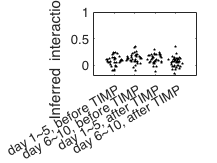

p-value for F-test for equal variance


first 5 days before TIMP vs. first 5 days after TIMP :


0.68865


last 5 days before TIMP vs. first 5 days after TIMP :


0.67965


first 5 days after TIMP vs. last 5 days after TIMP :


0.29232


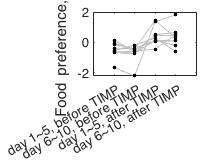

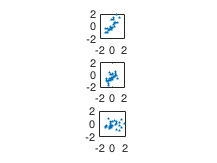


function s2 = my_load_data(nstrain, di, df, sub_flag)

if nargin < 4
    sub_flag = 0;
end

    s2 = [];
    for dayId = di:df
            
        fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];
        
        load(fn,'s');
        s = s';
        s = int64(s);
        s = remove_tunnel(s);
        
        s = s(:,1801:12600);

        if sub_flag
            if strcmp(nstrain, 'male_after_bsa_200727')
                s = s([1:7 9:10],:); % no dead or immobilized mouse
            end

            if strcmp(nstrain, 'male_before_bsa_200713')
                s = s([1:2 4:8 10 12],:); % no dead or immobilized mouse
            end

            if strcmp(nstrain, 'female_before_timp_180413')
                s = s([1:12 14],:); % no dead or immobilized mouse
            end
        
            if strcmp(nstrain, 'female_after_timp_180430')
                s = s([1:12 14],:); % no dead or immobilized mouse
            end
        end
        s2 = [s2 s];
    end
end


function [llh2] = compute_loglikelihood(jij, hir, s)
% return 3 rows, 1st row 1/4, 2nd row independent (only h), 3rd row
% pairwise

[nNodes, nSamples] = size(s);
nStates = 4;

llh2 = zeros(3, nNodes);
    
jijMat = recoverUpt(jij, nNodes);
hirMat = reshape(hir, nNodes, nStates-1);
hirMat = [hirMat zeros(nNodes,1)];


for imice = 1:nNodes
%%
    llh_null = log(1/nStates); 
    llh2(1, imice) = llh_null;

    m = mean(s(imice,:) == (1:nStates)',2);
    llh_indep = sum (log(m) .* m);
    llh2(2, imice) = llh_indep;
    
    % compute_local_energy1.
   
    llh_pw = 0; 
    for t = 1:nSamples
        mys = s(:, t);
        localE = compute_local_energy1(mys, imice, jijMat, hirMat);
        
        localE2 = zeros(1, nStates);
        mys_temp = mys;
        for istate = 1:nStates
            mys_temp(imice) = istate;
            localE2(istate) = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
        end
        lh = exp(-localE) / sum(exp(-localE2));
        llh_pw = llh_pw + log(lh);
    end
    llh_pw = llh_pw / nSamples;
    llh2(3, imice) = llh_pw;
end

end


function [mi2] = compute_mi(s2, jij, hir)

%%
[nNodes, nSamples] = size(s2);
nStates = 4;

%%
[jijMat, hirMat] = matrix_form_jij_hir(jij, hir, nNodes, nStates);
localE3 = compute_localE3(s2, jijMat, hirMat, nStates);

%%
mi2 = zeros(nNodes,1); 
for imice = 1:nNodes
    m = mean(s2(imice,:) == (1:nStates)',2);
    entropy = - sum (m .* log2(m));
    
    ce2 = nan(1, nSamples);
    for isample = 1:nSamples
        myE = squeeze(localE3(imice, :, isample)) ;
        predProb = exp(-myE)./sum(exp(-myE));
        myCE = - sum(predProb .* log2(predProb));  % CE = conditional entropy
        ce2(isample) = myCE;
    end
    
    %%  
    mi2(imice) = entropy - mean(ce2);
end

end

function [jijMat, hirMat] = matrix_form_jij_hir(jij, hir, nNodes, nStates)
jijMat = recoverUpt(jij, nNodes);
hirMat = reshape(hir, nNodes, nStates-1);
hirMat = [hirMat zeros(nNodes,1)];

end

function [localE3] = compute_localE3(s2, jijMat, hirMat, nStates)
%%
[nNodes, nSamples] = size(s2);
localE3 = zeros(nNodes, nStates, nSamples);
for isample = 1:nSamples
    mys = s2(:,isample);
    for imice = 1:nNodes
        for istate = 1:nStates
            mys_temp = mys;
            mys_temp(imice) = istate;
            localE = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
            localE3(imice, istate, isample) = localE;
        end
    end
end

end

function [txt_star] = txt_star_from_pvalue(my_pvalue, ntest)
    if my_pvalue > 0.05 / ntest
        txt_star = 'n.s.';
    elseif my_pvalue > 0.01 / ntest
        txt_star = '*';
    elseif my_pvalue > 0.001 / ntest
        txt_star = '**';
    else 
        txt_star = '***';
    end
end
